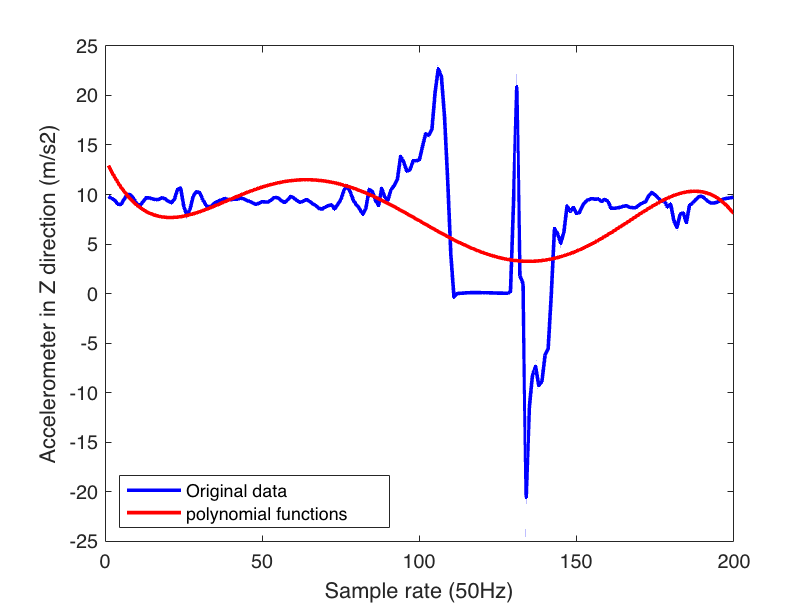

clc;
clear;

filename = 'data.mat';
data = load(filename);
x = data.data(:,1);
y = data.data(:,2);
z = data.data(:,3);

%% polynomial refression 
% figure(1)
p = polyfit([1:length(z)],z, 5);
z_poly = polyval(p, [1:length(z)]);
plot(z,'blue','Linewidth',2);
hold on;
plot(z_poly,'red','Linewidth',2);
xlabel('Sample rate (50Hz)'); 
ylabel('Accelerometer in Z direction (m/s2)'); 
legend('Original data', 'polynomial functions','Location','southwest'); 

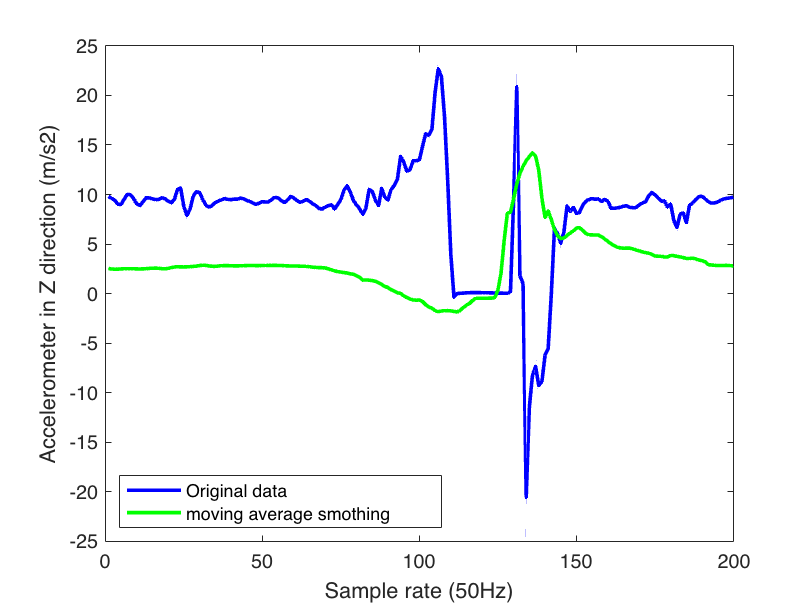

%% Smoothing
figure(2)
z_mv = smoothdata(y,'movmean',12);
plot(z,'blue','Linewidth',2);
hold on;
plot(z_mv,'green','Linewidth',2);
xlabel('Sample rate (50Hz)'); 
ylabel('Accelerometer in Z direction (m/s2)'); 
legend('Original data', 'moving average smothing','Location','southwest'); 

## Sum of squre errors and R2

yresid_poly = z - z_poly;
sse_poly = sum(sum(yresid_poly.^2));
SStotal_poly = (size(z,1)-1) * var(z);
r2_poly = 1 - sse_poly/SStotal_poly;


yresid_mv = z - z_mv;
sse_mv = sum(sum(yresid_mv.^2));
SStotal_mv = (size(z,1)-1) * var(z);
r2_mv = 1 - sse_mv/SStotal_mv;

disp('R2 and sum of square error for polynomial regressiono:')

R2 and sum of square error for polynomial regressiono:


fprintf('R2 = %2.2f, sum of square error = %2.2f\n', r2_poly, sse_poly)

R2 = -248.64, sum of square error = 1406808.48



disp('R2 and sum of square error for moving average:')

R2 and sum of square error for moving average:


fprintf('R2 = %2.2f, sum of square error = %2.2f\n', r2_mv, sse_mv)

R2 = -1.71, sum of square error = 15249.85
